f = @(x) sin(x.^2)

f = function_handle with value:
    @(x)sin(x.^2)


fp = @(x) 2*x .* cos(x.^2) % Derivata lui f

fp = function_handle with value:
    @(x)2*x.*cos(x.^2)


m = 9;
a = -2*pi;
b = 2*pi;
k = 0:m;
x = cos((2*k + 1)*pi/(2*m + 2)) * (b-a)/2 + (a + b)/2; % Noduri Chebysev #1
y = f(x);
yp = fp(x);

tt = linspace(a, b, 1000);
% L = Lagrange(x, y, tt);
c = barycentricweigths(x);
L = barycentricInterpolation(x, y, tt, c);

H = Hermite(x, y, yp, tt);

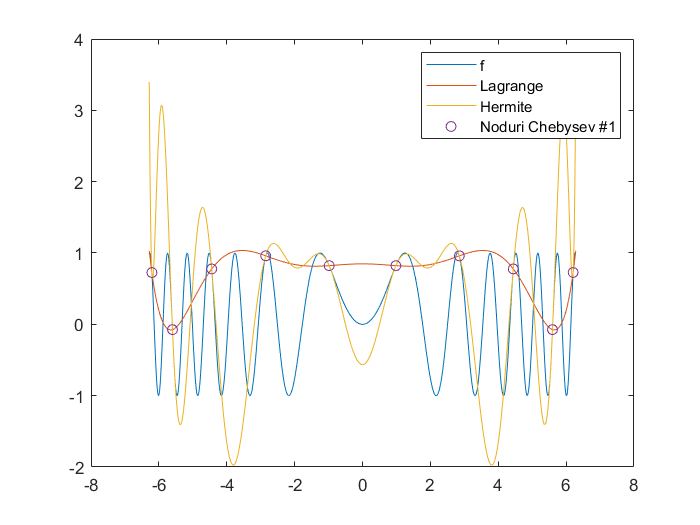

plot(tt, f(tt), tt, L, tt, H, x, y, 'o');
legend('f', 'Lagrange', 'Hermite', 'Noduri Chebysev #1');

Aproximare pentru $f\left(t\right),t=\frac{\pi }{5}$ 

t = pi/5;

L_t = Lagrange(x, y, t)

L_t = 0.8353

H_t = Hermite(x, y, yp, t)

H_t = 0.2454

f_t = f(t)

f_t = 0.3846

Eroarea teoretica

% Lagrange
syms x_sym
f_sym = sin(x_sym^2);
fdiff_sym(x_sym) = diff(f_sym, x_sym, m + 1);
LR_m_f = prod(x_sym - x) / factorial(m + 1) * fdiff_sym(x_sym)

$$LR\_m\_f = \frac{\left(x_{\mathrm{sym}}+\frac{2213309196611945}{2251799813685248}\right)\,\left(x_{\mathrm{sym}}+\frac{6303191990716993}{1125899906842624}\right)\,\left(x_{\mathrm{sym}}-\frac{4426618393223899}{4503599627370496}\right)\,\left(x_{\mathrm{sym}}-\frac{200727295769985}{70368744177664}\right)\,\left(x_{\mathrm{sym}}-\frac{1250560371546297}{281474976710656}\right)\,\left(x_{\mathrm{sym}}+\frac{1250560371546297}{281474976710656}\right)\,\left(x_{\mathrm{sym}}+\frac{6987142146276447}{1125899906842624}\right)\,\left(x_{\mathrm{sym}}+\frac{6423273464639519}{2251799813685248}\right)\,\left(x_{\mathrm{sym}}-\frac{3151595995358497}{562949953421312}\right)\,\left(x_{\mathrm{sym}}-\frac{218348192071139}{35184372088832}\right)\,\left(30240\,\cos\left({x_{\mathrm{sym}}}^{2}\right)-403200\,{x_{\mathrm{sym}}}^{4}\,\cos\left({x_{\mathrm{sym}}}^{2}\right)+23040\,{x_{\mathrm{sym}}}^{8}\,\cos\left({x_{\mathrm{sym}}}^{2}\right)-302400\,{x_{\mathrm{sym}}}^{2}\,\sin\left({x_{\mathrm{sym}}}^{2}\right)+161280\,{x_{\mathrm{sym}}}^{6}\,\sin\left({x_{\mathrm{sym}}}^{2}\right)-1024\,{x_{\mathrm{sym}}}^{10}\,\sin\left({x_{\mathrm{sym}}}^{2}\right)\right)}{3628800}$$

% In punctul t
LR_val = eval(subs(LR_m_f, x_sym, t))

LR_val = 1.9937e+03

% Hermite
HR_m_f = (prod(x_sym - x) .^ 2) / factorial(m + 1) * fdiff_sym(x_sym)

$$HR\_m\_f = \frac{{\left(x_{\mathrm{sym}}+\frac{2213309196611945}{2251799813685248}\right)}^{2}\,{\left(x_{\mathrm{sym}}+\frac{6303191990716993}{1125899906842624}\right)}^{2}\,{\left(x_{\mathrm{sym}}-\frac{4426618393223899}{4503599627370496}\right)}^{2}\,{\left(x_{\mathrm{sym}}-\frac{200727295769985}{70368744177664}\right)}^{2}\,{\left(x_{\mathrm{sym}}-\frac{1250560371546297}{281474976710656}\right)}^{2}\,{\left(x_{\mathrm{sym}}+\frac{1250560371546297}{281474976710656}\right)}^{2}\,{\left(x_{\mathrm{sym}}+\frac{6987142146276447}{1125899906842624}\right)}^{2}\,{\left(x_{\mathrm{sym}}+\frac{6423273464639519}{2251799813685248}\right)}^{2}\,{\left(x_{\mathrm{sym}}-\frac{3151595995358497}{562949953421312}\right)}^{2}\,{\left(x_{\mathrm{sym}}-\frac{218348192071139}{35184372088832}\right)}^{2}\,\left(30240\,\cos\left({x_{\mathrm{sym}}}^{2}\right)-403200\,{x_{\mathrm{sym}}}^{4}\,\cos\left({x_{\mathrm{sym}}}^{2}\right)+23040\,{x_{\mathrm{sym}}}^{8}\,\cos\left({x_{\mathrm{sym}}}^{2}\right)-302400\,{x_{\mathrm{sym}}}^{2}\,\sin\left({x_{\mathrm{sym}}}^{2}\right)+161280\,{x_{\mathrm{sym}}}^{6}\,\sin\left({x_{\mathrm{sym}}}^{2}\right)-1024\,{x_{\mathrm{sym}}}^{10}\,\sin\left({x_{\mathrm{sym}}}^{2}\right)\right)}{3628800}$$

% In punctul t
HR_val = eval(subs(HR_m_f, x_sym, t))

HR_val = -2.0123e+08

Eroarea practica

% In aproximarea lui t
err_L_t = abs(L_t - f_t) / f_t

err_L_t = 1.1717

err_H_t = abs(H_t - f_t) / f_t

err_H_t = 0.3620

% In interpolarea intregii functii
% Lagrange
err_L = abs(f(tt) - L);
fprintf("Lagrange Error Mean: %f, Min: %f, Max: %f", mean(err_L), min(err_L), max(err_L))

Lagrange Error Mean: 0.749889, Min: 0.002640, Max: 2.024515

% Hermite
err_H = abs(f(tt) - H);
fprintf("Hermite Error Mean: %f, Min: %f, Max: %f", mean(err_H), min(err_H), max(err_H))

Hermite Error Mean: 0.891482, Min: 0.000017, Max: 3.812976

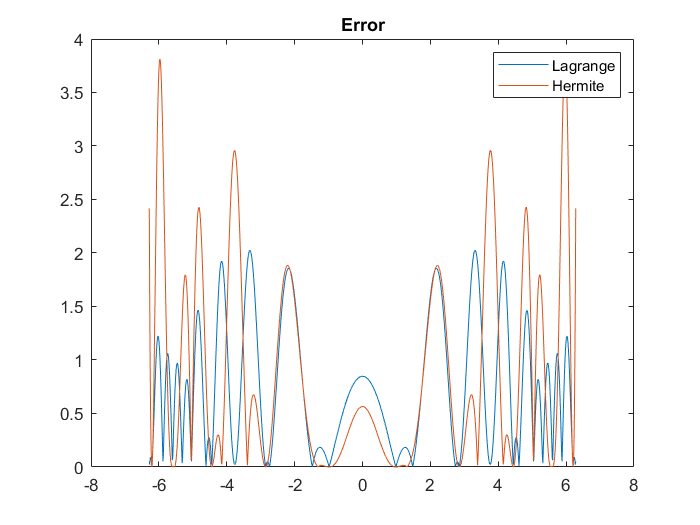

plot(tt, err_L, tt, err_H)
title('Error')
legend('Lagrange', 'Hermite')